# EEG Artifacts

This script investigates how tACS stimulation artifacts affect EEG/LFP analysis and shows results for FASTR, FBAR, and RBAR algorithms.

## Setup Simulation

First define the stimulation and recording parameters.

eegDefaults.reproducible              = true;    % Fix the random number generator to get reproducible results
%% Equipment:
eegDefaults.stimulatorSamplingRate    = 1e3;     % Neuroconn (2 kHz)
eegDefaults.recordingSamplingRate     = 5e3;     % 5kHz
eegDefaults.currentResolution         = 1e-6;    % 1 muA
eegDefaults.highPass                  = 0.01;    % Analog filter of the recording amplifier
%% Experiment:
eegDefaults.duration                  = 2*60;   % 2 min of data
eegDefaults.tacsFrequency             = 0;
eegDefaults.tacsAmplitude             = 0;
eegDefaults.tdcsMean                  = 0;
%% Data:
eegDefaults.additive                  = 100e-6;   % Background Noise stdev


And setup the base parameters for artifiact removal

arDefaults.slide                     = false;   % No sliding segment
arDefaults.slack                     = 5e-3;    % 5 ms to realign segments
arDefaults.nrSegsPerWindow           = 10;      % 10 segments to average artifact
arDefaults.pcaNr                     = 2;       % First two PC are removed
arDefaults.pcaVarExplained           = Inf;     % Ignore explained variance, always remove 2.
arDefaults.pcaNrSegsPerWindow        = Inf;     % Use all segments (plus the tACS signal; below) to determine basis set.
arDefaults.referenceSegment          = 1;       % Align to first segment

## Recovering the neural background with FASTR

Create the artSim object using the parameters defined above, then add tACS stimulation to the simulation 

eeg = artSim(eegDefaults);
eeg.tacsAmplitude             = 1e-3;    % 1 mA -> 1 mV artifact
eeg.tacsFrequency             = 10;      % 10 Hz


First, investigate the FASTR algorithm (Niazy et al.). Match the artificat removal parameters to the data

ar                          = arDefaults;
ar.tacsFrequency            = eeg.tacsFrequency;
ar.recordingSamplingRate    = eeg.recordingSamplingRate;
ar.nrCycles                 = 30;      % 30 cycles per segment


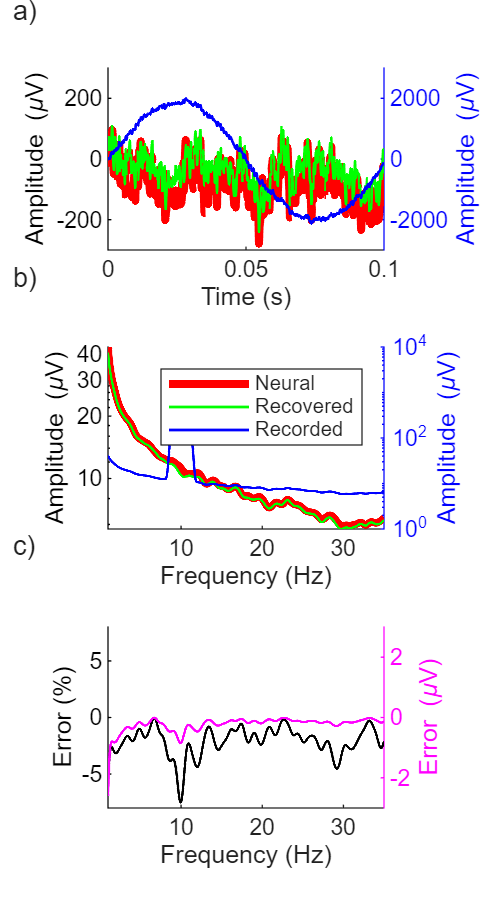

Allocating memory...


ans = 0.0085


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.94 rmse = 18/100 muV ae = 2.1%)


[f,axs] = fig('Name','Fig2','nrCols',1,'height',12,'nrRows',3,'byColumn',false);

simPlotEEG(eeg,ar,'FASTR',axs=axs);

Note that the Neural ground truth and the Recovered signals are generally small and show on the left y-axis. The recorded signal, which includes the artifact, is typically orders of magnitude larger - this graph shows it (blue) on the right y-axis. The figure shows that the recovered signal qualitatively matches the neural signal (green vs.red), but a  closer look , expressing errors as a percentage of the neural signal show substantial underestimation of the neural signal not only near the tACS frequency, but across the entire spectrum. 

The low-resolution spectral analysis hides some important detals. Rerun it now with 0.1 Hz frequency resolution:

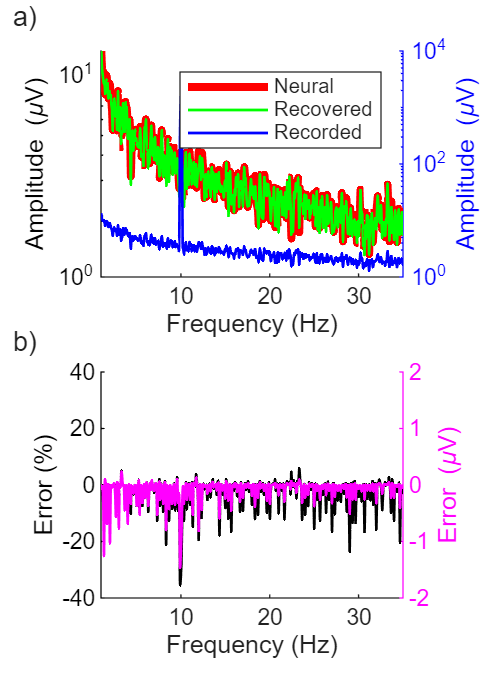

Allocating memory...


ans = 0.0085


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.94 rmse = 18/100 muV ae = 2.8%)


[f,axs] = fig('Name','Fig3','paperCols',1,'height',9,'nrRows',2,'byColumn',false);

simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[gobjects(1) axs']);

This shows the clear comb artifact that repeats at `o.tacsFrequency/o.nrCycles`, here 10/30 = 0.33 Hz.

## Recovering neural signals and background

Next, we *add* a neural signal in the form of an LFP/EEG signal that peaks at 32 hz, with some spectral spread around that:

eeg.lfpFrequency              = 32;        % Simulated oscillation peak frequency
eeg.lfpAmplitude              = 100e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 1;         % Oscillation bandwidth.

[~,axs4] = fig('Name','Fig4','paperCols',2,'height',10,'nrRows',3,'nrCols',1,'byColumn',false);
[~,axs5] = fig('Name','Fig5','paperCols',2,'height',5,'nrRows',1,'nrCols',3,'byColumn',false);


### FASTR


simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[axs4(1) gobjects(1) axs5(1)]);

Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.96 rmse = 21/100 muV ae = 2.9%)


### FBAR

We continue analyzing the same data, but now with a Fourier based algorithm (FBAR), using the same parameters


simPlotEEG(eeg,ar,'FBAR',freqRes =0.1,axs=[axs4(2) gobjects(1)  axs5(2)]);

FBAR (r=0.97 rmse = 16/100 muV ae = 0.7%)


### RBAR

And a regression based method:

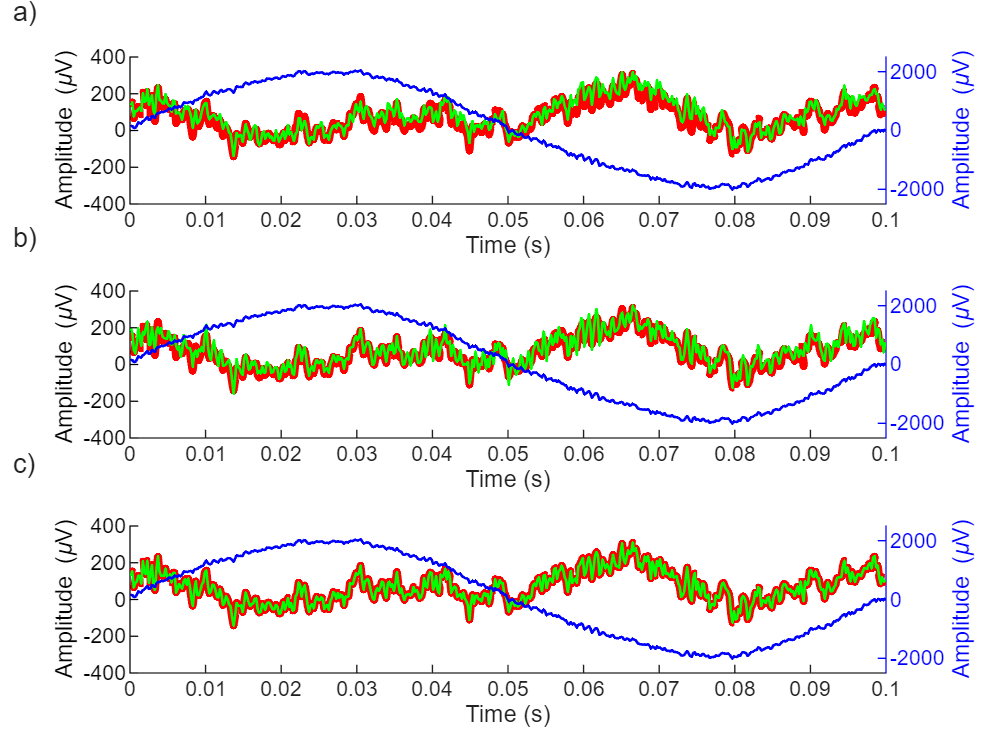

RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


simPlotEEG(eeg,ar,'RBAR',freqRes =0.1,axs=[axs4(3)  gobjects(1) axs5(3)]);

This graph shows a 100 ms snippet of the data (red; with the 32 Hz oscillation) and recovered signal (green). Visually, FASTR does not recover the original signal, while FBAR and RBAR do.

This is easier to see in the spectral domain:

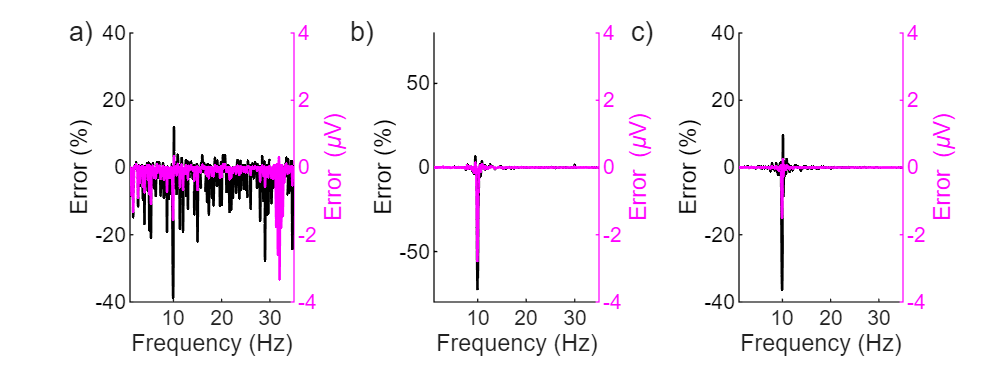

linkaxes(axs5)

FASTR has serious issues across the spectrum,  FBAR & RBAR perform substantially better, recovering most of the spectrum, except for a narrow bound around the tACS frequency.

## Recovering Neural Signal in the Presence of Impedance Artifacts

Physiological artifacts such as heartbeats, sweating, or breathing change impedance and interact multiplicatively with the signal. FASTR has a hard time recovering any underlying signals.

Keeping the neural signals from above, but adding an artifact that rhytmically (`o.zFrequency`) changes the impedance sinusoidally, or abruptly for short periods of time (`o.zDuration`). The maximum change in the impedance is defined (as a fraction) by `o.zAmplitude.`

eeg                           = artSim(eegDefaults);      % Start fresh
eeg.tacsAmplitude             = 1e-3;    % 1 mA -> 1 mV artifact
eeg.tacsFrequency             = 10;      % 10 Hz
eeg.lfpFrequency              = 32;        % Simulated oscillation peak frequency
eeg.lfpAmplitude              = 100e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 1;         % Oscillation bandwidth.

Restore ar parameters

ar                          = arDefaults;
ar.tacsFrequency            = eeg.tacsFrequency;
ar.recordingSamplingRate    = eeg.recordingSamplingRate;
ar.nrCycles                 = 30;      % 30 cycles per segment


Add physiological arfitacts, first a sinusoidal modulation of the impedance (maybe a reasonable approximation for respiration not so much for a heartbeat):

eeg.zFrequency = 23/60;  % 23 breaths per minute
eeg.zAmplitude = 0.05;  % The artifact changes the impedance by 5%.
eeg.zDuration = 0;      % Purely sinusoidal
[f,axs] = fig('Name','Fig6','paperCols',1.5,'height',9,'nrRows',2,'nrCols',2);

First we simulate

simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[gobjects(1,2) axs(1)]);

Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.95 rmse = 27/100 muV ae = 8.4%)


simPlotEEG(eeg,ar,'RBAR',freqRes =0.1,axs=[gobjects(1,2) axs(2)]);

RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


Next we simulate a impedance modulation that is more abrupt (akin to the ballistic artifacts expected from a heartbeat). 

eeg.zFun = @zHeartbeat ;
%eeg.zFrequency = 53/60; % 53 BPM
%eeg.zDuration  = 0.05;  %  Short pulses
simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[gobjects(1,2) axs(3)]);

Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 21/100 muV ae = 3.6%)


simPlotEEG(eeg,ar,'RBAR',freqRes =0.1,axs=[gobjects(1,2) axs(4)]);

RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


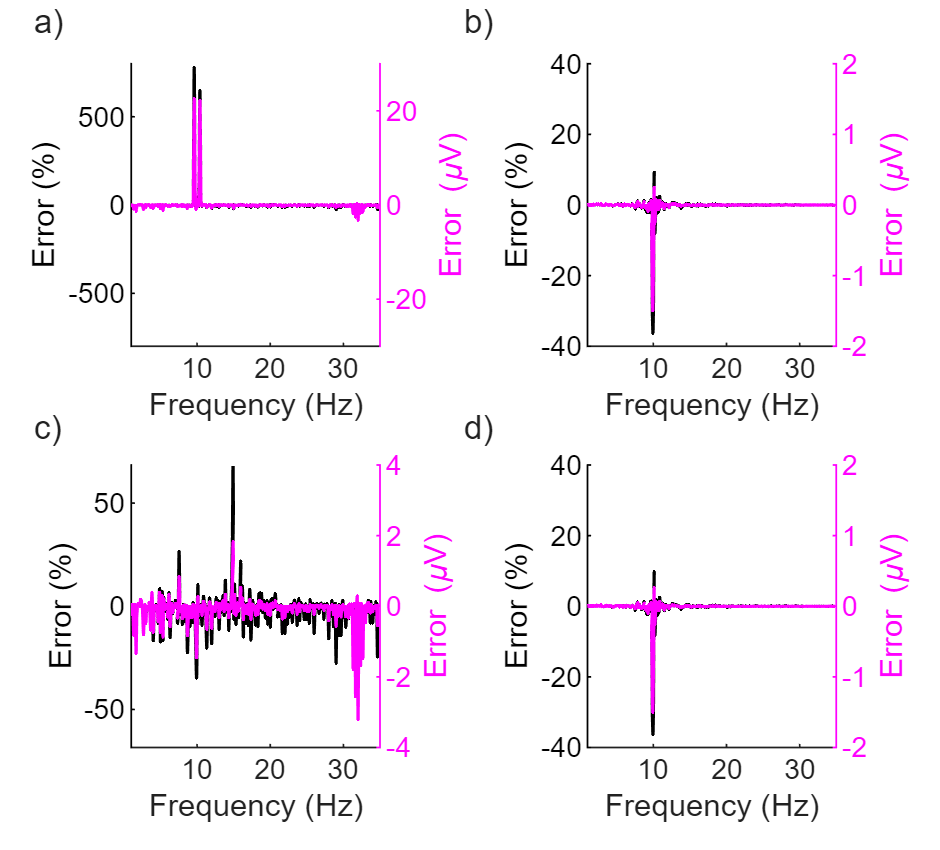

linkaxes(axs([2 4]))

Clearly FASTR (a,c) does not recover the neural signal of either sinusoidal (a) or pulsed (c) impedance artifacts; the multiplicative interactions between physiological artifacts and the true neural signal results in spurious signals across the entire spectrum.  Noury et al explain why this should happen and why there are two prominent peaks in a).  RBAR gets rid of most artifacts and only has a small forbidden zone near the tACS frequency. FBAR (not shown) has the same kind of issues as FASTR.

### tDCS 

As long as recordings exclude the ramp up and ramp down periods, the DC current generated by tDCS does not introduce neural artifacts on its own.  

However, impedance artifacts induced by physiological changes such as heartbeats can result in spurious neural signals. 

eeg                           = artSim(eegDefaults);      % Start fresh
eeg.tdcsMean                  = 1e-3;
eeg.lfpFrequency              = 23;        % Simulated oscillation peak frequency
eeg.lfpAmplitude              = 100e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 0;         % Oscillation bandwidth.
eeg.duration                  = 120;
eeg.pinkNoise =true;
eeg.zFun  =  @zHeartbeat;
eeg.zAmplitude = 0.05;  % The artifact changes the impedance by 5%.


Restore ar parameters

ar                          = arDefaults;
ar.recordingSamplingRate    = eeg.recordingSamplingRate;
ar.segmentDuration          = 120;      


[f,axs] = fig('Name','FigtDCS','paperCols',2,'height',9,'nrRows',3,'nrCols',1);


Simulate a impedance modulation that follows a ECG recording. 

tlim = [0.2 0.8];
simPlotEEG(eeg,ar,'NOP',freqRes =1,axs=[axs(1) gobjects(1,1) axs(2)],tlim=tlim);

NOP (r=1.00 rmse = 4/100 muV ae = 0.9%)


z = eeg.zFun(eeg); 
axes(axs(1))
yyaxis left
stay  = eeg.tSimulate>tlim(1) & eeg.tSimulate < tlim(2); 
plot(eeg.tSimulate(stay)-min(eeg.tSimulate(stay)),max(ylim)*(z(stay)-1)/eeg.zAmplitude,'c-');

simPlotEEG(eeg,ar,'RBAR',freqRes =1,axs=[gobjects(1,2) axs(3)]);

RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)


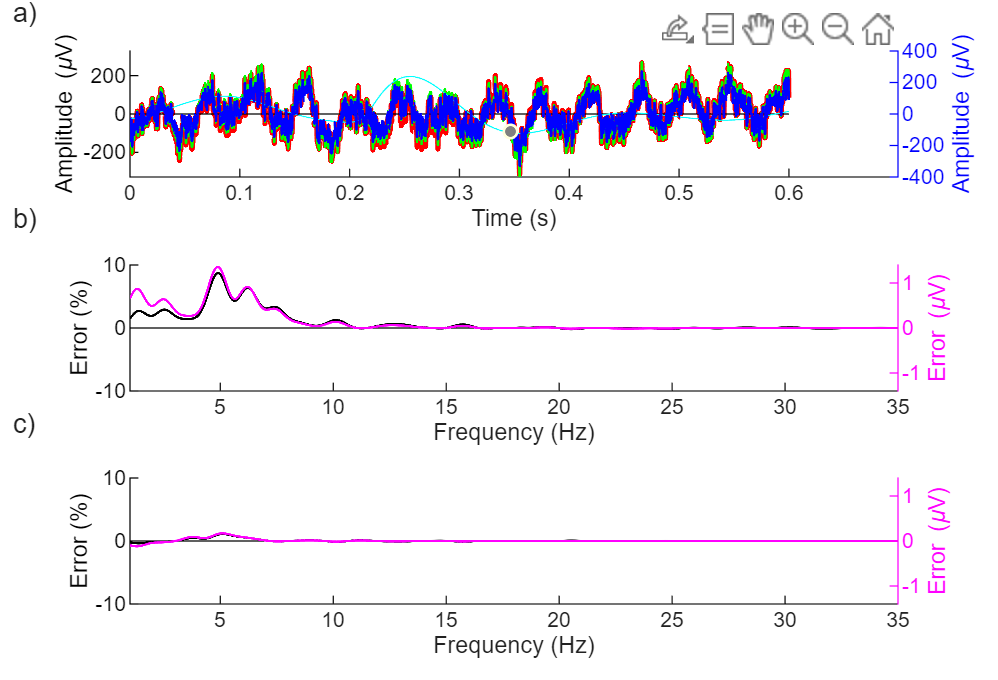

linkaxes(axs([2 3]));
axes(axs(2));yyaxis left;axes(axs(3));yyaxis left;
linkaxes(axs([2 3]));

## Signal frequency dependence

The above analysis focuses only on a single intrinsic oscillation, here I do repeat this for a range of frequencies to show that the relative performance of the methods is approximately the same no matter what the neural signal is. 

eeg                  = artSim(eegDefaults); % Start fresh
eeg.lfpAmplitude     = 100e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth     = 5;        % Oscillation bandwidth.
eeg.tacsAmplitude    = 1e-3;    % 1 mA -> 1 mV artifact
eeg.tacsFrequency    = 10;      % 10 Hz


methods = ["FASTR","FBAR", "RBAR"];
signalFreqs = 2.^(0:5);  % Test these frequencies
nrFreqs = numel(signalFreqs);
nrMethods = numel(methods);
forbiddenBand = nan(nrFreqs,nrMethods);
forbidden = nan(nrFreqs,nrMethods);
mre = nan(nrFreqs,nrMethods);
for m=1:nrMethods
    for  f = 1:nrFreqs
        eeg.lfpFrequency = signalFreqs(f);
        results = simPlotEEG(eeg,ar,methods(m),freqRes =0.1,axs=[nan nan nan],errorThreshold=1,fillHz=0.1);  % Same analysis as above, without figure
        forbiddenBand(f,m) = results.forbiddenBand;
        forbidden(f,m) = results.forbidden;
        mre(f,m) = results.meanPctError;
    end
end
clf;
subplot(1,2,1)
plot(signalFreqs,forbidden)
xlabel 'Signal Frequency (Hz)'
ylabel 'Forbidden (Hz)'

subplot(1,2,2)
plot(signalFreqs,forbiddenBand)
xlabel 'Signal Frequency (Hz)'
ylabel 'Forbidden in-band (Hz)'

mean(forbidden)
std(forbidden)
mean(mre)



## Segment length dependence

RBAR does a good job removing artifacts, but it still has a ~2 Hz forbidden zone in the simulations above. Because the residual artifacts are essentially due to the windowing/segmenting, this can be improved by increasing segment size. Note, however, that this comes at a cost of a reduced ability to follow changes in the artifacts over time (i.e. dealing with non-stationary artifacts). The simulation below has a stationary artifact hence it ignores this tradeoff. 

eeg.lfpAmplitude              = 50e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 1;        % Oscillation bandwidth.
eeg.zAmplitude        = 0;        % No physiolgical artifact
eeg.lfpFrequency              = 20;

nrCyclesPerSegment = [10 20 40 80 160];
nrSims = numel(nrCyclesPerSegment);
methods = ["FASTR","FBAR", "RBAR"];
nrMethods = numel(methods);
forbidden = nan(nrSims,nrMethods);
mre = nan(nrSims,nrMethods);
for m=1:nrMethods
    for  s = 1:nrSims
        ar.nrCycles= nrCyclesPerSegment(s);
        results = simPlotEEG(eeg,ar,methods(m),freqRes =0.1,axs=[nan nan],errorThreshold=1,fillHz=0.1);
        forbidden(s,m) = results.forbidden;
        mre(s,m) = results.meanPctError;
    end
end

[f,axs] = fig('Name','RBAR.Fig5','paperCols',1,'height',5,'nrRows',1,'nrCols',1);
yyaxis left
plot(nrCyclesPerSegment',forbidden(:,3))
xlabel 'nrCycles per Segment'
ylabel 'Forbidden (Hz)'
yyaxis right
plot(nrCyclesPerSegment',mre(:,3))
ylabel 'mre (%)'

The figure confirms that the forbidden zone (and the mre) decrease rapidly with increasing segment sizes (here expressed in the number of tACS cycles per segment).